%%
x = [0 60 120 180 240 300]

x =      0    60   120   180   240   300


y = [1 1.4 1.9 1.7 1.5 1.2]

y =     1.0000    1.4000    1.9000    1.7000    1.5000    1.2000



y.*cosd(x);
sum(y.*cosd(x))

ans = -1.1000

y.*sind(x);
sum(y.*sind(x))

ans = 0.5196

y.*cosd(2.*x);
sum(y.*cosd(2.*x))

ans = -0.3000

y.*sind(2*x);
sum(y.*sind(2.*x))

ans = -0.1732


%%
x = 0:60:300

x =      0    60   120   180   240   300


x1 = x;
y = [1 1.4 1.9 1.7 1.5 1.2]

y =     1.0000    1.4000    1.9000    1.7000    1.5000    1.2000


T = 2 * pi

T = 6.2832

w = (2*pi)/T

w = 1


x = (pi/180)*x 

x =          0    1.0472    2.0944    3.1416    4.1888    5.2360


syms t;

a0 = 2 * mean(y);
HS = a0 / 2;

h = 2; % number of harmonics
for i=1:h
    a(i) = 2 * mean(y.*cos(i*w*x));
    b(i) = 2 * mean(y.*sin(i*w*x));
    
    HS = HS + a(i) * cos(i*w*t) + b(i) * sin(i*w*t);
end
HS = vpa(HS, 4);

disp(HS);

$$0.1732\,\sin\left(t\right)-0.05774\,\sin\left(2.0\,t\right)-0.3667\,\cos\left(t\right)-0.1\,\cos\left(2.0\,t\right)+1.45$$

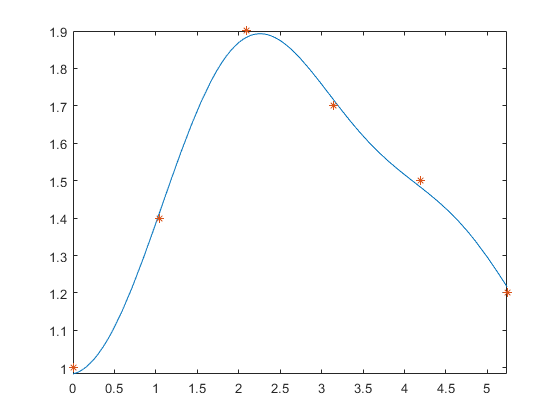


fplot(HS, [x(1) x(end)])
hold on;
plot(x, y ,'*')

% t = linspace(x(1), x(end), 1000);
% y1 = eval(HS);
% plot(t, y1, 'r');

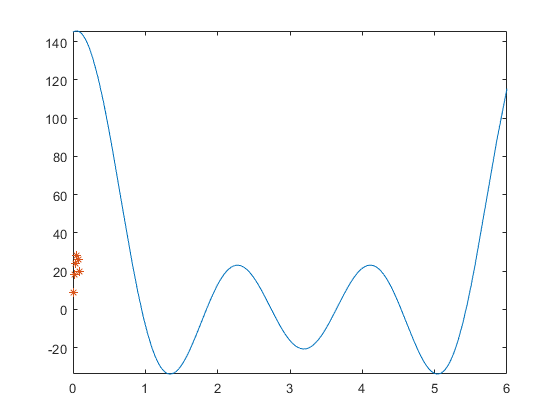

hold off

x = [0 1 2 3 4 5]

x =      0     1     2     3     4     5


y = [9 18 24 28 26 20]

y =      9    18    24    28    26    20


$$41.41\,\cos\left(2.0\,t\right)+4.107\,\sin\left(2.0\,t\right)+41.08\,\cos\left(3.0\,t\right)+6.138\,\sin\left(3.0\,t\right)+41.6\,\cos\left(t\right)+2.058\,\sin\left(t\right)+20.83$$

harmonic_anal(x, y);